# Project 2

In collaboration with: Caleb Rudick, Michael Klein Wassink

## Part 1

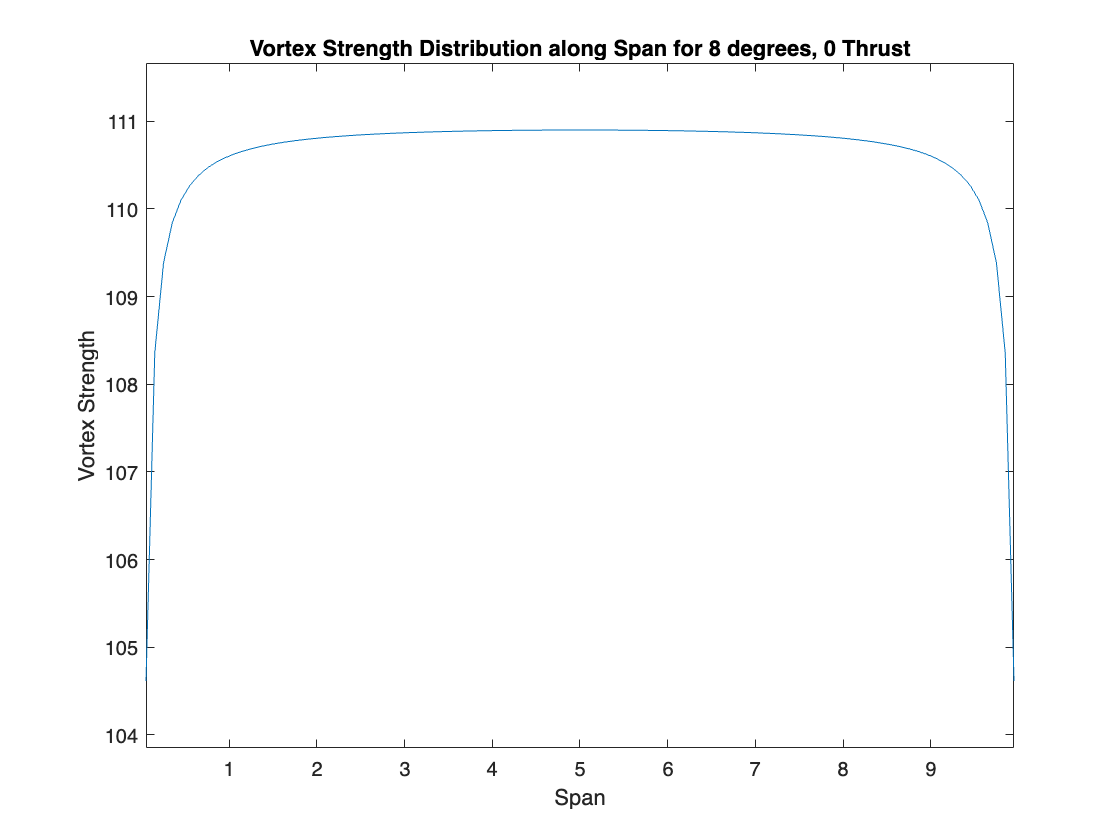

clc
clear 
close all

% initialize parameters
v_inf = 168.8;
c = 1.5;
b = 10;
n = 100;
k = n+1;

% initialize y_trailing and y_bound
y_trail = zeros(k,1);
step = b/n;
for i = 1:k
    y_trail(i) = step*(i-1);
end
y_bound = y_trail(1:n)+(step/2);

% initialize angle of attack of geometry, induced, and effective
alpha_g = 8 * (pi/180) * ones(n,1);
alpha_eff = alpha_g;

% coefficient of lift
Cl = 2 * pi * alpha_eff;

% gamma for a specific boundary
gamma_bn = 0.5 * Cl * v_inf * c;
gamma_bn_new = gamma_bn+1;

% while gamma has not yet converged
while ((mean(gamma_bn) - mean(gamma_bn_new)) / mean(gamma_bn) < 0.0001)
% || ((gamma_bn(1)-gamma_bn_new(1))/gamma_bn(1) < 0.0001)
% while (gamma_bn(1)-gamma_bn_new(1))/gamma_bn(1) < 0.0001
    gamma_tk = zeros(k,1);
    for i = 2:n
        gamma_tk(i) = gamma_bn(i)-gamma_bn(i-1);
    end
    gamma_tk(1) = gamma_bn(1);
    gamma_tk(k) = -gamma_bn(n);
    
    for n=1:n
        for k=1:k
            v_ind(n,k) = -gamma_tk(k)/(4*pi*(y_bound(n)-y_trail(k)));
        end
    end
    
    v_ind_new = sum(v_ind,2); 
    alpha_i = atan(-v_ind_new/v_inf);
    alpha_eff = alpha_g - alpha_i;
    Cl = 2 * pi * alpha_eff;
    gamma_bn_new = 0.5 * Cl * v_inf*c;
    gamma_bn = gamma_bn + 0.01*(gamma_bn_new-gamma_bn); 
end
        
plot(y_bound, gamma_bn);
title('Vortex Strength Distribution along Span for 8 degrees, 0 Thrust')
ylabel('Vortex Strength')
xlabel('Span')
axis equal

## Part 2

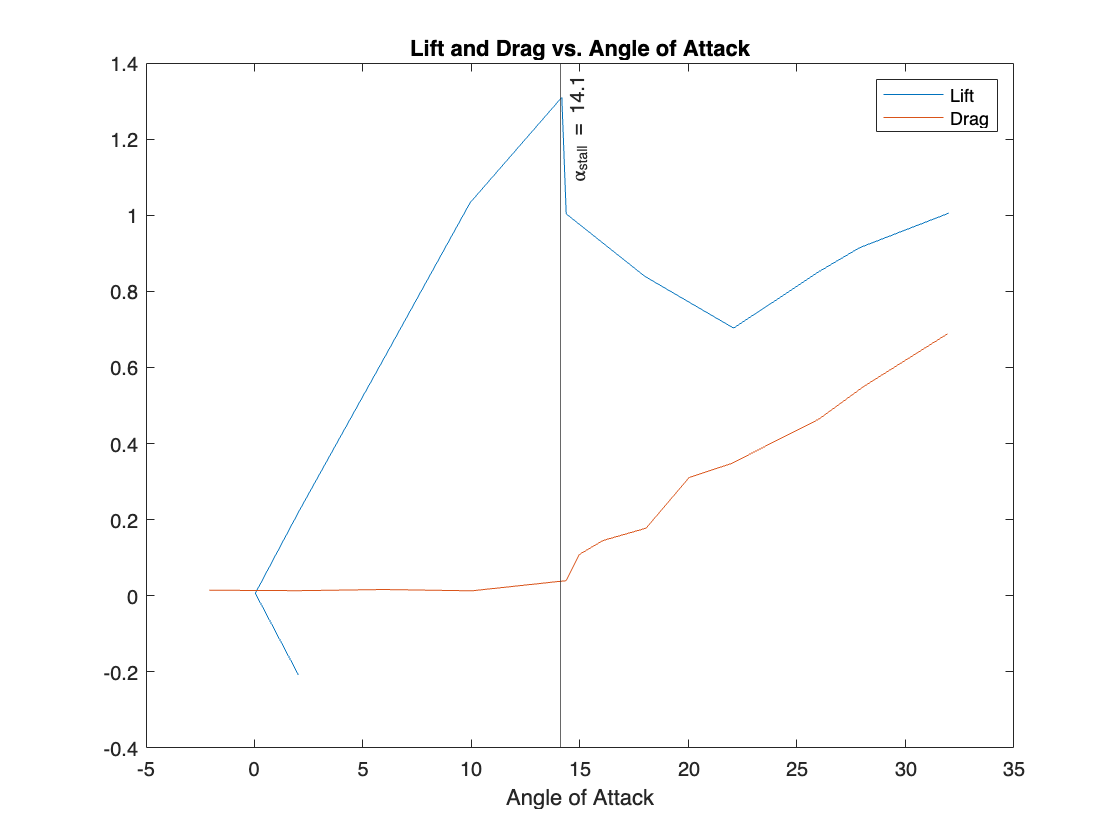

clc
clear
close all

load('cl_cd.mat');
plot(Cl_0012(:,1),Cl_0012(:,2));
hold on;
plot(Cd_0012(:,1),Cd_0012(:,2));
title('Lift and Drag vs. Angle of Attack')
xline(14.1, '-', {'\alpha_{stall} = 14.1'});
legend('Lift', 'Drag')
xlabel('Angle of Attack')
hold off;

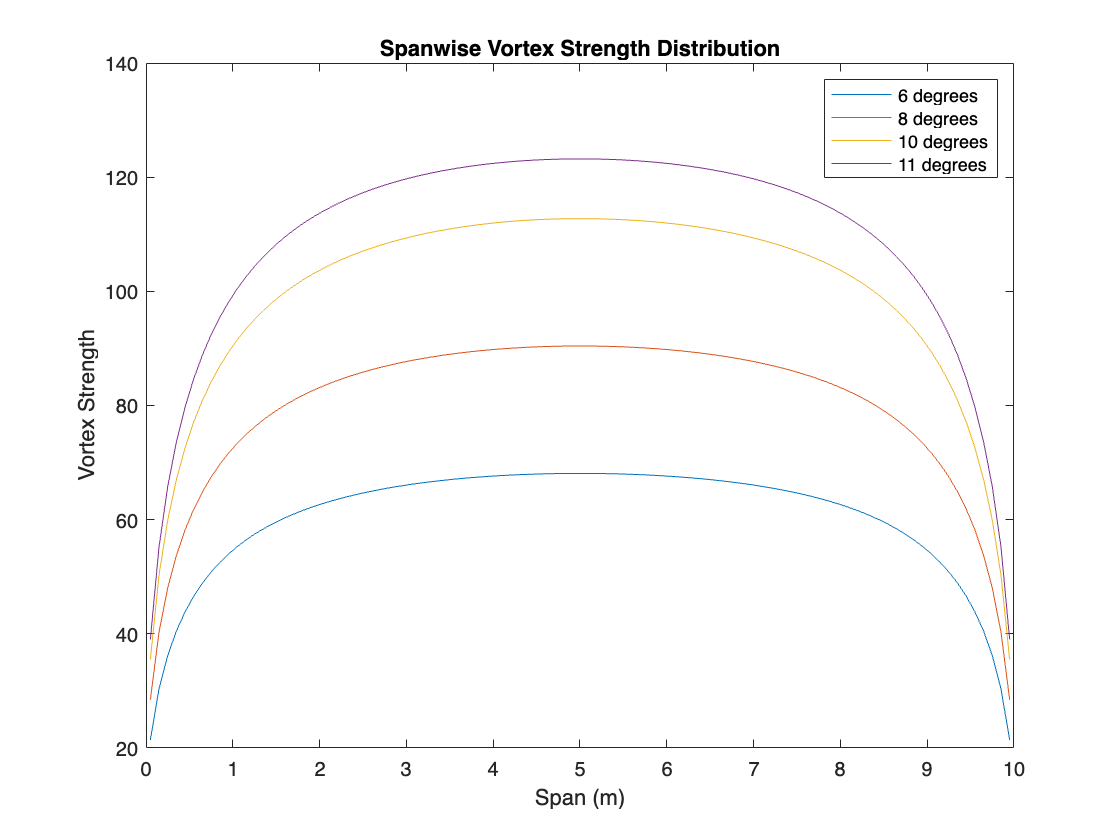


[y_bound, gamma_bn, ~, ~] = part2(6);
plot(y_bound, gamma_bn);
hold on;
[y_bound, gamma_bn, ~, ~] = part2(8);
plot(y_bound, gamma_bn);
[y_bound, gamma_bn, ~, ~] = part2(10);
plot(y_bound, gamma_bn);
[y_bound, gamma_bn, ~, ~] = part2(11);
plot(y_bound, gamma_bn);
legend('6 degrees', '8 degrees', '10 degrees', '11 degrees');
title('Spanwise Vortex Strength Distribution')
ylabel('Vortex Strength')
xlabel('Span (m)')
hold off;

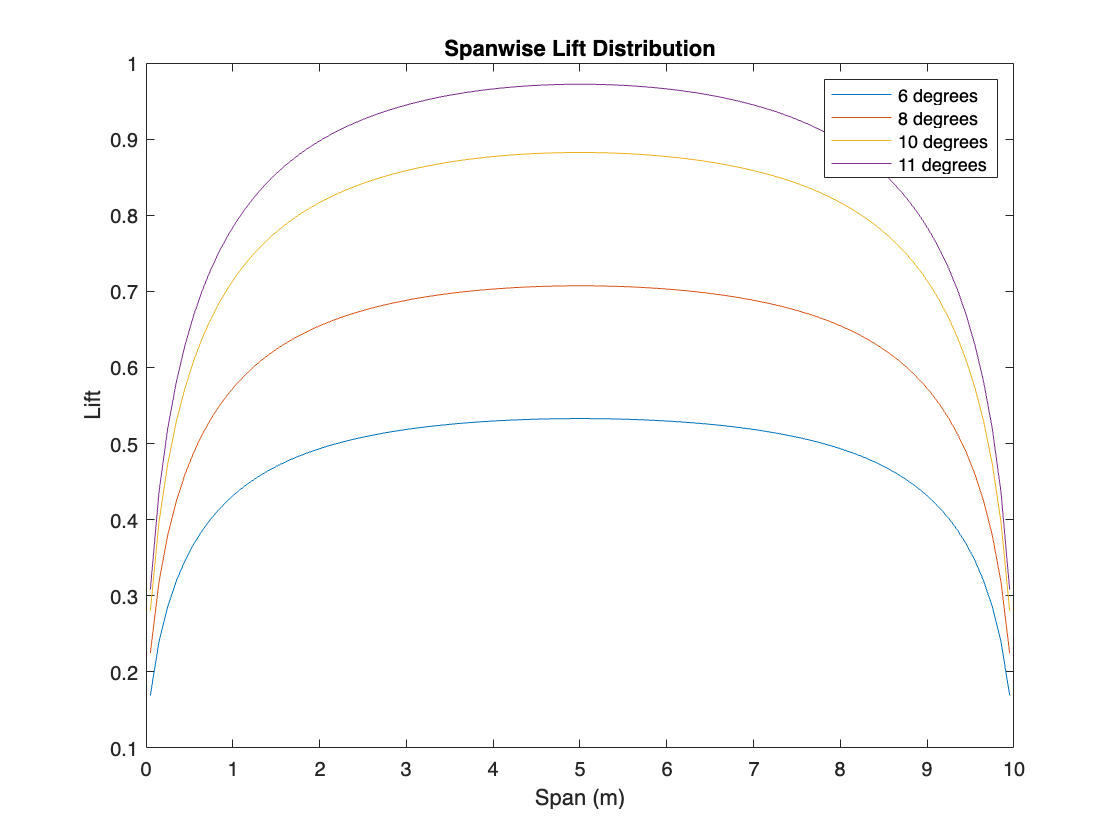


[~, ~, Cl, ~] = part2(6);
plot(y_bound, Cl);
hold on;
[~, ~, Cl, ~] = part2(8);
plot(y_bound, Cl);
[~, ~, Cl, ~] = part2(10);
plot(y_bound, Cl);
[~, ~, Cl, ~] = part2(11);
plot(y_bound, Cl);
legend('6 degrees', '8 degrees', '10 degrees', '11 degrees');
title('Spanwise Lift Distribution')
ylabel('Lift')
xlabel('Span (m)')
hold off;

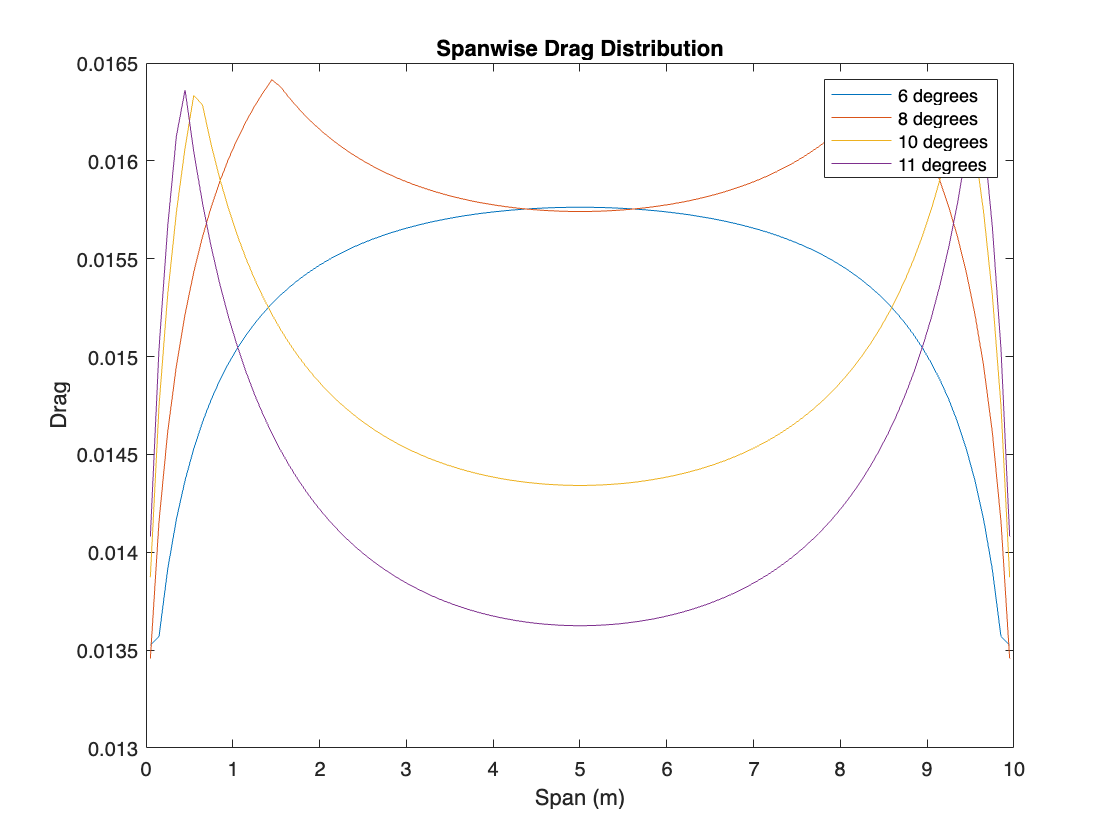


[~, ~, ~, Cd] = part2(6);
plot(y_bound, Cd);
hold on;
[~, ~, ~, Cd] = part2(8);
plot(y_bound, Cd);
[~, ~, ~, Cd] = part2(10);
plot(y_bound, Cd);
[~, ~, ~, Cd] = part2(11);
plot(y_bound, Cd);
legend('6 degrees', '8 degrees', '10 degrees', '11 degrees');
title('Spanwise Drag Distribution')
ylabel('Drag')
xlabel('Span (m)')
hold off;

## Part 3

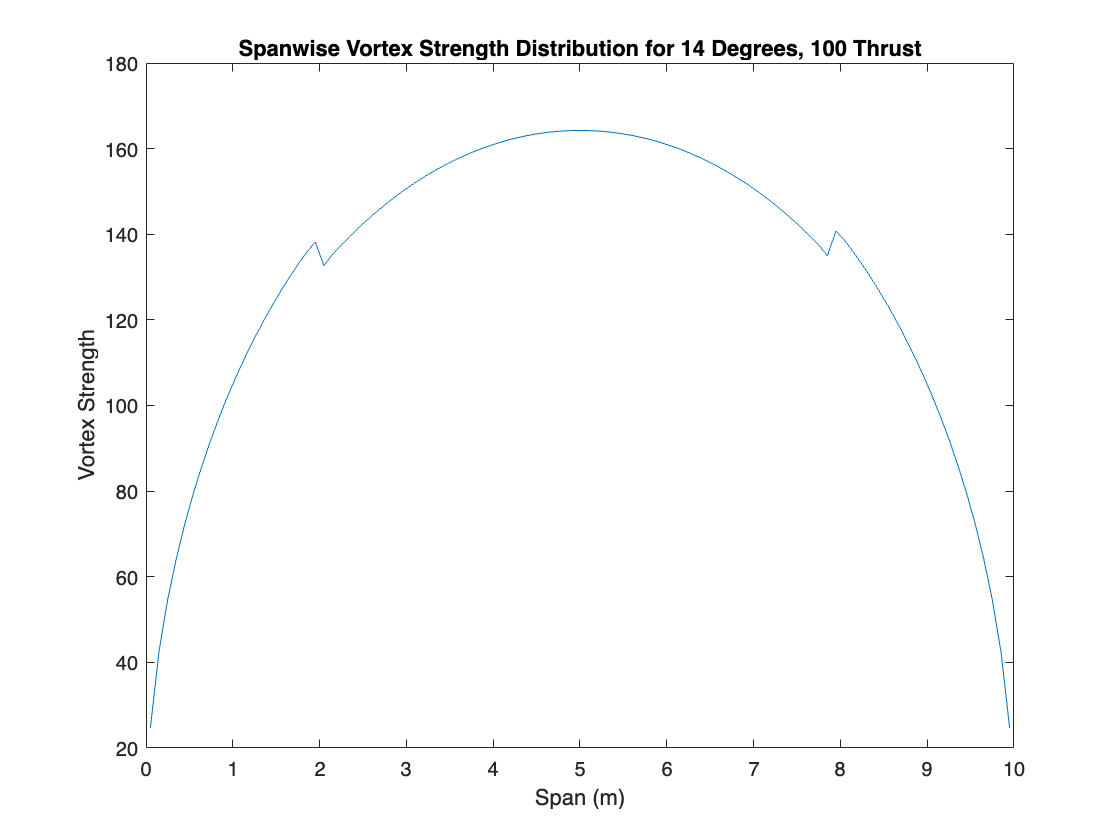

clc
clear
close all

[y_bound, gamma_bn, ~, ~] = part3(100, 14);
plot(y_bound, gamma_bn)
title('Spanwise Vortex Strength Distribution for 14 Degrees, 100 Thrust')
xlabel('Span (m)')
ylabel('Vortex Strength')

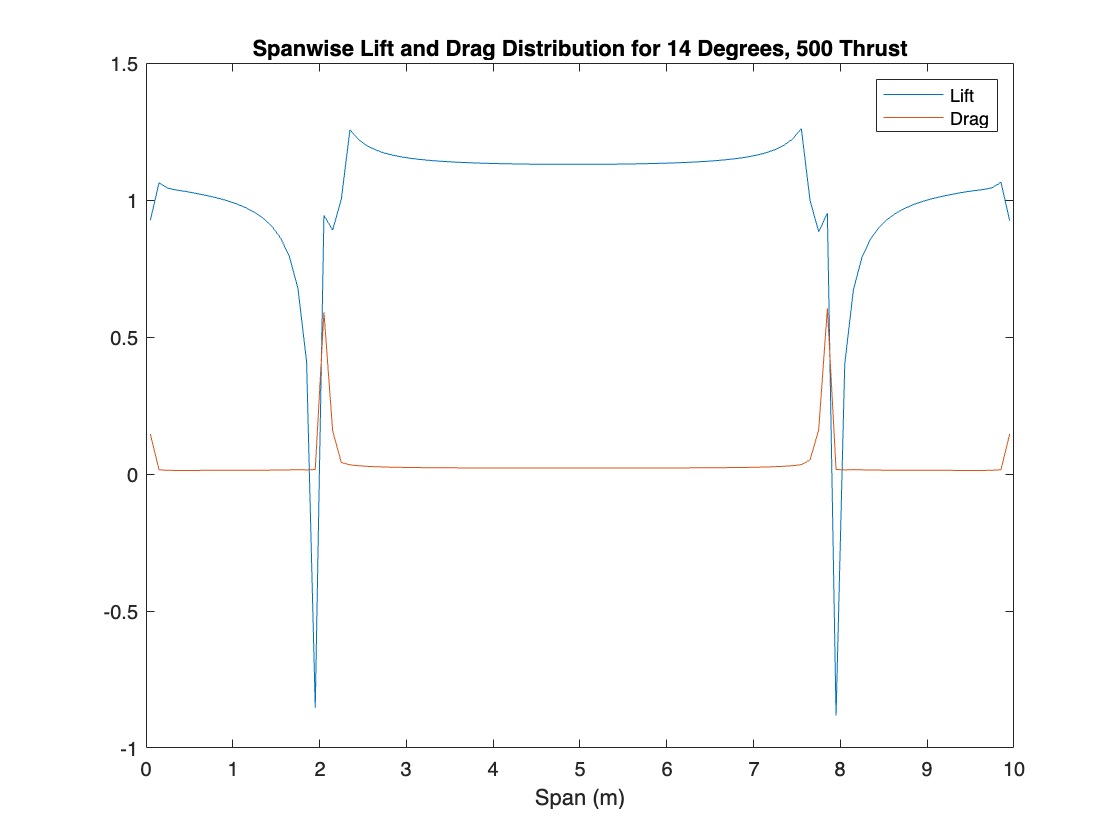

[y_bound, ~, Cl, Cd] = part3(500, 14);
plot(y_bound, Cl)
title('Spanwise Lift and Drag Distribution for 14 Degrees, 500 Thrust')
xlabel('Span (m)')
hold on
plot(y_bound, Cd)
legend('Lift', 'Drag')
hold off

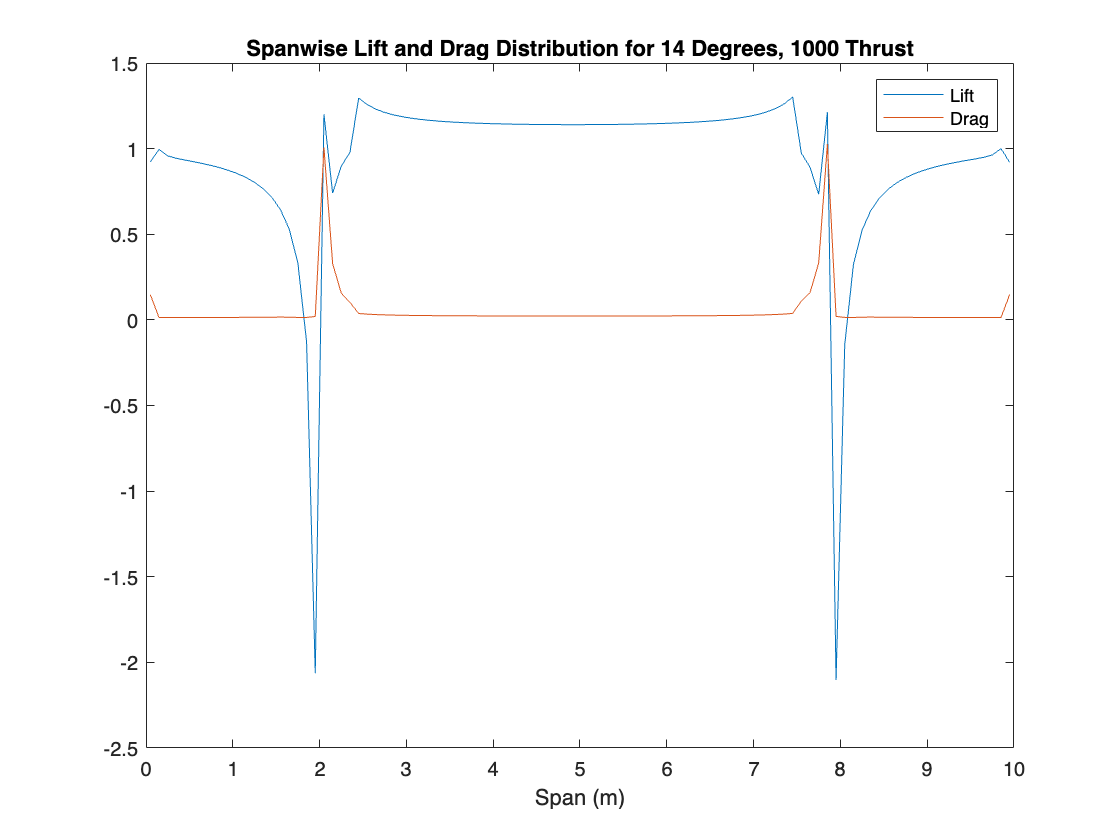


[y_bound, ~, Cl, Cd] = part3(1000, 14);
plot(y_bound, Cl)
xlabel('Span (m)')
title('Spanwise Lift and Drag Distribution for 14 Degrees, 1000 Thrust')
xlabel('Span (m)')
hold on
plot(y_bound, Cd)
legend('Lift', 'Drag')
hold off